% Specify the folder you want to add
folderToAdd = 'C:\Users\Zwivh\OneDrive - University of Cape Town\5th Year\1st Semester\EEE4118F\tut 5';

% Add the folder to the MATLAB search path
addpath(folderToAdd);

% Save the path for future sessions
savepath;

% Check for Robust Control Toolbox license
toolbox_name = 'Robust Control Toolbox'; 
if ~license('test', toolbox_name)
    disp(['License for ' toolbox_name ' not available.']);
else
    disp(['Loading ' toolbox_name '...']);
    % The toolbox is automatically available if licensed
    disp(['Loaded ' toolbox_name '.']);
end

License for Robust Control Toolbox not available.


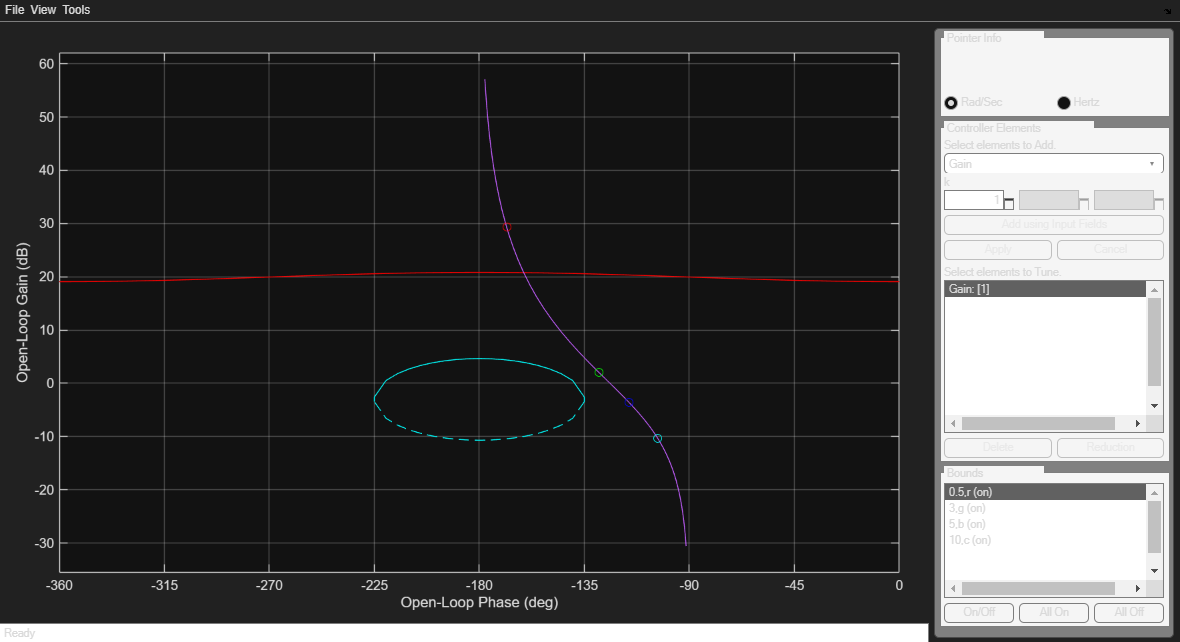


% Define transfer function and bounds
s = tf('s'); 
P = (0.000635/s) * exp(-3.59);  % Use exp instead of e for MATLAB syntax
%bnd = sisobnds(2, [0.5, 3, 5, 10], 10.^([-20, 3, 3, 3]/20), P); 
%lpshape(logspace(-1, 2), bnd, P); 

% Define the loop transfer function and sensitivity
G = (338286.5716*0.5/s)*(s+2.411);
L = G * P;  % Forms LTI objects for loop transfer functions for all P 
Sensitivity = 1/(1 + L); 

bnd = sisobnds(2, [0.5, 3, 5, 10], 10.^([-20, 3, 3, 3]/20), L); 
lpshape(logspace(-1, 2), bnd, L); 

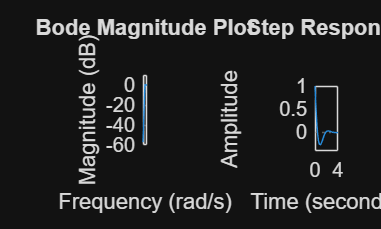


% Plot Bode magnitude and step response
figure;
subplot(121), bodemag(Sensitivity); 
grid on;  % Add grid for better visualization
title('Bode Magnitude Plot');

subplot(122), step(Sensitivity);

title('Step Response');

